# DVB-S2 Receiver Using SDR

#### Clear out the environment

clear; close all; clc;

#### **Download DVB-S2 LDPC Parity Matrices Data Set**


if ~exist('dvbs2xLDPCParityMatrices.mat','file')
    if ~exist('s2xLDPCParityMatrices.zip','file')
        url = 'https://ssd.mathworks.com/supportfiles/spc/satcom/DVB/s2xLDPCParityMatrices.zip';
        websave('s2xLDPCParityMatrices.zip',url);
        unzip('s2xLDPCParityMatrices.zip');
    end
    addpath('s2xLDPCParityMatrices');
end

#### SDR Setup

useSDR = true;
fileName = "dvbs2ModCod24Waveform.mat";
if useSDR
    rxsim.DeviceName = "Pluto";
    rxsim.RadioCenterFrequency = 915e6;
    rxsim.RadioGain = 0;
end

#### **Initialize Receiver Parameters**

- The **preferred loop bandwidth** for symbol timing and coarse frequency compensation depends on the SNR setting: SNR low, loop bandwidth should be reduced to filter out more noise

- The **number of frames** required for the symbol synchronization and frame synchronization depends on the loop bandwidth setting.

- Set `rxParams.symbSyncLock `to` ceil(1e5/rxParams.plFrameSize)` for low SNR

- Set `rxParams.frameSyncLock` to a value in the range of [5, 15] frames for SNR < 1 dB

fecFrame = "short";                             % DVB-S2 FECFrame type
modCod = 18;                                    % 32APSK 3/4
Fsamp = 2e6;                                    % Sampling rate in samples per second
Rsym = 1e6;                                     % Symbol rate in symbols per second
sps = Fsamp/Rsym;

rxParams = getRxParams(fecFrame,modCod);
rxParams.carrSyncLoopBW            = 1e-3;      % Coarse frequency estimator loop bandwidth normalized by symbol rate
rxParams.symbSyncLoopBW            = 1e-4;      % Symbol timing synchronizer loop bandwidth normalized by symbol rate
rxParams.symbSyncLock              = 2;         % Number of frames required for symbol timing error convergence
rxParams.frameSyncLock             = 1;         % Number of frames required for frame synchronization
rxParams.sps = sps;
% Total frames taken for symbol timing and frame synchronization to happen
rxParams.initialTimeSync = rxParams.symbSyncLock + rxParams.frameSyncLock;

#### **Capture DVB-S2 Waveform Using SDR**

numFrames = 50;                                                  % Number of PL frames to capture
enableBurstMode       = true;
numFramesInBurst      = numFrames;
if useSDR
    if matches(rxsim.DeviceName,"Pluto")
        radioRx = sdrrx("Pluto");
        radioRx.RadioID               = "usb:0"; % Left
        radioRx.CenterFrequency       = rxsim.RadioCenterFrequency;
        radioRx.BasebandSampleRate    = Fsamp;
        radioRx.GainSource            = "Manual";
        info(radioRx) % Output radio info
    elseif matches(rxsim.DeviceName,"N3xx/X3xx/X410")
        savedRadioConfigurations = radioConfigurations;
        savedRadioConfigurationNames = [string({savedRadioConfigurations.Name})];
        % Specify the index of the saved radio configuration to be utilized
        % as the receiver
        radioIndex = 1;
        radio = savedRadioConfigurationNames(radioIndex);
        if ~exist("bbrx","var")
            radioRx = basebandReceiver(radio);
        end        
        radioRx.RadioGain = rxsim.RadioGain;
        radioRx.SampleRate = Fsamp;
        radioRx.CaptureDataType = "double";
        radioRx.CenterFrequency = rxsim.RadioCenterFrequency;
    else
        connectedRadios = findsdru;
        rIdx = find(strcmp(rxsim.DeviceName,{connectedRadios.Platform}));
        if strcmp(connectedRadios(rIdx).Status,"Success")
            usrpRx.Platform = connectedRadios(rIdx).Platform;
            switch usrpRx.Platform
                case {'B200','B210'}
                    usrpRx.SerialNum = connectedRadios(rIdx).SerialNum;
                    usrpRx.MasterClockRate = 20e6;
                case 'N200/N210/USRP2'
                    usrpRx.IPAddress = connectedRadios(rIdx).IPAddress;
                    usrpRx.MasterClockRate = 100e6;
                otherwise
                    error("%s\n","Unsupported USRP device");
            end
        end
    
    switch usrpRx.Platform
        case {'B200','B210'}
            radioRx = comm.SDRuReceiver( ...
                Platform         =    usrpRx.Platform, ...
                SerialNum        =    usrpRx.SerialNum, ...
                CenterFrequency  =    rxsim.RadioCenterFrequency, ...
                MasterClockRate  =    usrpRx.MasterClockRate, ...
                DecimationFactor =    usrpRx.MasterClockRate/Fsamp);
        case 'N200/N210/USRP2'
            radioRx = comm.SDRuReceiver( ...
                Platform         =   usrpRx.Platform, ...
                IPAddress        =   usrpRx.IPAddress, ...
                CenterFrequency  =   rxsim.RadioCenterFrequency, ...
                MasterClockRate  =   usrpRx.MasterClockRate, ...
                DecimationFactor =   usrpRx.MasterClockRate/Fsamp);      
    end
    end
    if matches(rxsim.DeviceName,"N3xx/X3xx/X410")
        rxDuration = numFrames*(rxParams.plFrameSize*sps)/radioRx.SampleRate;
        [rxIn,~] = capture(radioRx,milliseconds(rxDuration*1e3));
    else
        radioRx.Gain                 = rxsim.RadioGain;                            % In dB
        radioRx.OutputDataType       = "double";
        radioRx.SamplesPerFrame      = rxParams.plFrameSize*sps;
        if enableBurstMode
            radioRx.EnableBurstMode  = enableBurstMode;
            radioRx.NumFramesInBurst = numFramesInBurst;
        end
        disp(radioRx)
        rxLength   = numFrames*radioRx.SamplesPerFrame;
        rxIn       = zeros(rxLength,1) + 1i*zeros(rxLength,1);
        for l = 1:numFrames
            [rxIn((l-1)*radioRx.SamplesPerFrame+1:l*radioRx.SamplesPerFrame),numSamps,overrun] = radioRx();
            if overrun && ~radioRx.EnableBurstMode
                fprintf("Overrun detected in loop #%d\n",l);
            end
        end
        release(radioRx);
    end    

## Establishing connection to hardware. This process can take several seconds.


ans = struct with fields:
                     Status: 'Full information'
            CenterFrequency: 915000000
         BasebandSampleRate: 1999999
                  SerialNum: '10447318ac0f0016ecff0e00677f17b7db'
                       Gain: 10
       RadioFirmwareVersion: "0.38"
    ExpectedFirmwareVersion: "0.38"
            HardwareVersion: "C1"


  comm.SDRRxPluto with properties:

   Main
                DeviceName: 'Pluto'
                   RadioID: 'usb:0'
           CenterFrequency: 915000000
                GainSource: 'Manual'
                      Gain: 0
            ChannelMapping: 1
        BasebandSampleRate: 2000000
            OutputDataType: 'double'
           SamplesPerFrame: 8424
           EnableBurstMode: true
          NumFramesInBurst: 50
    ShowAdvancedProperties: false

  Show all properties



## Establishing connection to hardware. This process can take several seconds.


#### **Import Waveform from File**

- `rxIn = txOut` is added to fix the unrecognised `rxIn` bug.

- The result is accurate, as it was obtained directly from the captured file.

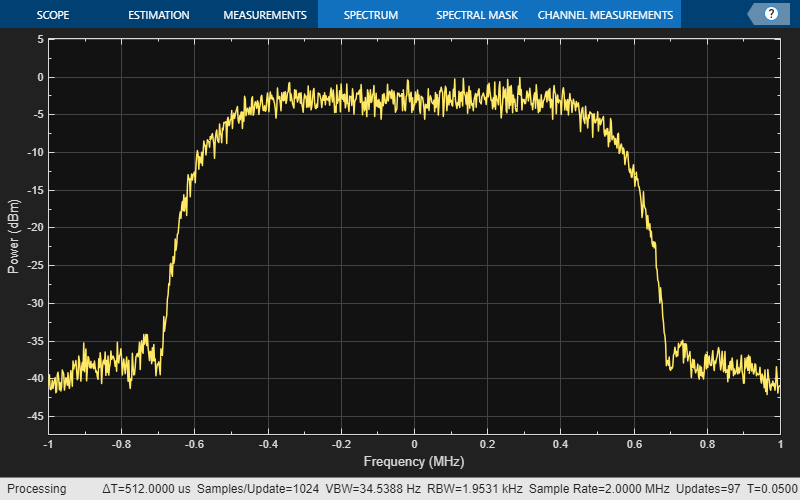

else
    fprintf("Reading DVB-S2 IQ data from a captured file\n")
    load(fileName)
    rxIn = txOut; % added
end

% Preproccessing the captured parameter

rxIn = rxIn./(max(abs(rxIn)));
rxParams.initialTimeFreqSync = numFrames;
rxParams.totalSyncFrames = numFrames;

#### **Visualize Received Waveform**

The **spectrum** of the captured waveform:

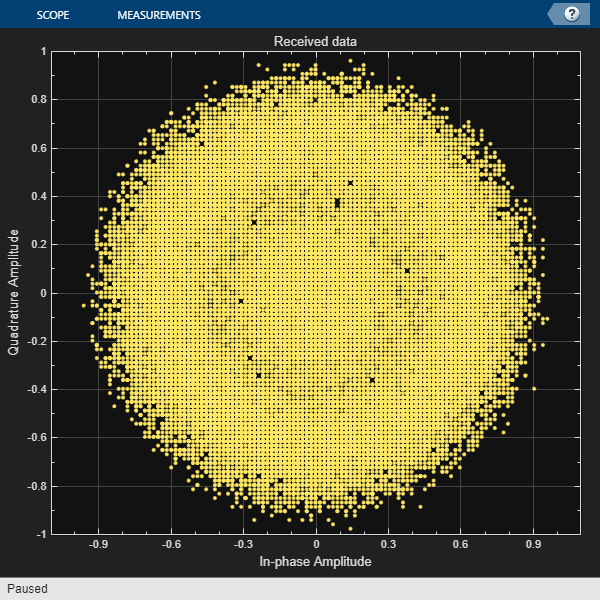

specAn = spectrumAnalyzer(SampleRate=Fsamp);

specAn(rxIn(1:100000));

The **constellation** of the captured waveform:

rxConst = comm.ConstellationDiagram(Title="Received data", ...
    AxesLimits=[-1 1], ...
    ShowReferenceConstellation=false, ...
    SamplesPerSymbol=rxParams.sps);
rxConst(rxIn(1:100000))

#### **Initialize Receiver Processing System Objects**

- `HelperDVBS2TimeFreqSynchronizer` helper object: A time and coarse frequency synchronization System object

- `comm.AGC`

- `dsp.DCBlocker`

- `comm.ConstellationDiagram`

timeFreqSync = HelperDVBS2TimeFreqSynchronizer( ...
    CarrSyncLoopBW=rxParams.carrSyncLoopBW, ...
    SymbSyncLoopBW=rxParams.symbSyncLoopBW, ...
    SamplesPerSymbol=rxParams.sps, ...
    DataFrameSize=rxParams.xFecFrameSize, ...
    SymbSyncTransitFrames=rxParams.symbSyncLock, ...
    FrameSyncAveragingFrames=rxParams.frameSyncLock);

agc = comm.AGC(AveragingLength=2000,AdaptationStepSize = 0.001);

dcBlock = dsp.DCBlocker(Algorithm="FIR",Length=100);

syncConst = comm.ConstellationDiagram( ...
        Title="Synchronized data", ...
        AxesLimits=[-2 2], ...
        ShowReferenceConstellation = false);

[numFramesLost,pktsErr,bitsErr,pktsRec,stIdx,numFreqEst] = deal(0);

% Initialize data indexing variables
plFrameSize = rxParams.plFrameSize;
symSyncOutLen = zeros(rxParams.initialTimeFreqSync,1);
freqCounter = 0;
isCoarseFreqLock = false;
cCFOEstMean = [];
isFineFreqLock = false;
cCFOEst = [];
rxParams.fineFreqEstTemp = zeros(numFrames-rxParams.initialTimeSync,1);

frameIdx = 0

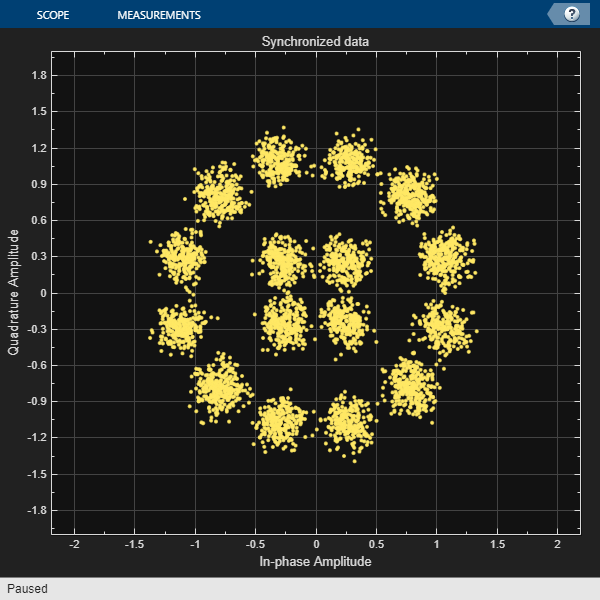

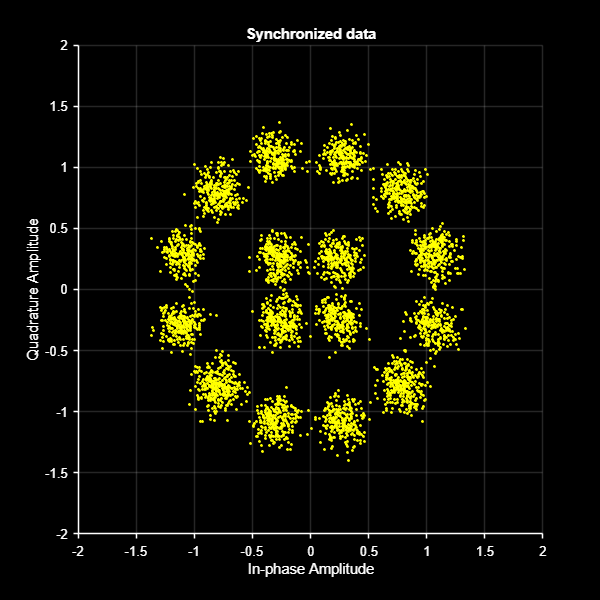

Estimated carrier frequency offset in Hz = 124.981293


Physical layer header detection summary


detPLParams = 1×4 table
    Modulation    Code Rate    FEC Frame    Pilot Status
    __________    _________    _________    ____________

     "16APSK"       "2/3"       "short"        "true"   


headerDataDisplayCounter = 0;
streamFormat = "packetized";

#### **Synchronization and Data Recovery**

- **Comment out **PL frame number (line 355), Estimated SNR (line 356), BB header (line 366) & Total number of frames lost (line 378) to reduce output length.

- Add animated GIF functionality

gifFilename = "rx_syn_constellation_mark5.gif";
delayTime  = 0.3;       % seconds between frames
hGifFig = figure('Renderer','zbuffer','Visible','on');  
frameIdx = 0

while stIdx < length(rxIn)

    % Use one DVB-S2 PL frame for each iteration.

PER: 2.94e-02


    endIdx = stIdx + rxParams.plFrameSize*rxParams.sps;

    % In the last iteration, consider all the remaining samples in the received
    % waveform.
    isLastFrame = endIdx > length(rxIn);
    endIdx(isLastFrame) = length(rxIn);
    rxData = rxIn(stIdx+1:endIdx);

    % After coarse frequency offset loop is converged, the FLL works with a
    % reduced loop bandwidth.
    if rxParams.frameCount < rxParams.initialTimeFreqSync
        isCoarseFreqLock = false;
    else
        isCoarseFreqLock = true;
    end

    % Retrieve the last frame samples.
    if isLastFrame
        resSymb = plFrameSize - length(rxParams.cfBuffer);
        resSampCnt = resSymb*rxParams.sps - length(rxData);
        if resSampCnt >= 0                                    % Inadequate number of samples to fill last frame
            syncIn = [rxData;zeros(resSampCnt,1)];
        else                                                  % Excess samples are available to fill last frame
            syncIn = rxData(1:resSymb*rxParams.sps);
        end
    else
        syncIn = rxData;
    end

    % Apply DC offset compensation, AGC, matched filtering, symbol timing synchronization, frame
    % synchronization, and coarse frequency offset compensation.
    syncIn = dcBlock(syncIn);
    syncIn = agc(syncIn);
    if rxParams.frameCount > 1
        [coarseFreqSyncOut,syncIndex,phEst] = timeFreqSync(syncIn,isCoarseFreqLock);
        coarseCFOEst = diff(phEst(1:sps:end)/(2*pi));
        if rxParams.frameCount <= rxParams.initialTimeSync
            symSyncOutLen = [symSyncOutLen;length(coarseFreqSyncOut)]; %#ok<*AGROW>
            if any(abs(diff(symSyncOutLen(1:rxParams.frameCount))) > 5)
                error(["Symbol timing synchronization failed. The loop will not " ...
                    "converge, resulting in frame recovery. Decrease the symbSyncLoopBW " ...
                    "parameter for proper loop convergence."]);
            end
        end
        if rxParams.frameCount > rxParams.initialTimeSync + 1
            cCFOEstMean = [cCFOEstMean;mean(coarseCFOEst)];
            cCFOEst = [cCFOEst;coarseCFOEst];
            if length(cCFOEstMean) > 2
                diffVal = diff(abs(cCFOEstMean));
                if all(diffVal(end-1:end) < 0.01) && ~isCoarseFreqLock
                    isCoarseFreqLock = true;
                    rxParams.initialTimeFreqSync = rxParams.frameCount;
                elseif isLastFrame && ~isCoarseFreqLock
                   fprintf("%s\n",["Coarse frequency error estimation failed. Try analyzing the cCFOEst " ...
                       "across frames and check carrier synchronization has converged. Try reducing the " ...
                       "carrSyncLoopBW parameters"]);
                end
            end
        end
        rxParams.syncIndex = syncIndex;
        % The PL frame start index lies somewhere in the middle of the frame being processed.
        % From fine frequency estimation, the processing happens as a PL frame.
        % A buffer stores the symbols required to fill one PL frame.
        if isLastFrame
            fineFreqIn = [rxParams.cfBuffer; coarseFreqSyncOut];
        elseif rxParams.frameCount > 1
            buffLen = rxParams.plFrameSize - length(rxParams.cfBuffer);
            if buffLen < length(coarseFreqSyncOut)
                fineFreqIn = [rxParams.cfBuffer; coarseFreqSyncOut(1:buffLen)];
            else
                fineFreqIn = [rxParams.cfBuffer; coarseFreqSyncOut];
            end
        end
        % Estimate the fine frequency error by using the HelperDVBS2FineFreqEst
        % helper function.
        % Add 1 to the conditional check because the buffer used to get one PL
        % frame introduces a delay of one to the loop count.
        if (rxParams.frameCount > rxParams.initialTimeFreqSync + 1) && ...
                ~isFineFreqLock
            rxParams.fineFreqCorrVal = HelperDVBS2FineFreqEst( ...
                fineFreqIn(rxParams.pilotInd),rxParams.numPilots, ...
                rxParams.refPilots,rxParams.fineFreqCorrVal);
            % Normalize the frequency estimate by the input symbol rate
            % freqEst = angle(R)/(pi*(N+1)), where N (18) is the number of elements
            % used to compute the mean of auto correlation (R) in
            % HelperDVBS2FineFreqEst.
            freqEst = angle(rxParams.fineFreqCorrVal)/(pi*(19));
            rxParams.fineFreqEstTemp(1:end-1) = rxParams.fineFreqEstTemp(2:end);
            rxParams.fineFreqEstTemp(end) = freqEst;
            numFreqEst = numFreqEst + 1;
            if numFreqEst >= 5
                cg = abs(diff(rxParams.fineFreqEstTemp));
                if all(cg(end-2:end) < 1e-4)
                    isFineFreqLock = true;
                    rxParams.totalSyncFrames = rxParams.frameCount;
                    fprintf("Estimated carrier frequency offset in Hz = %f\n",(coarseCFOEst(end) + freqEst).*Rsym);
                elseif isLastFrame && ~isFineFreqLock
                    fprintf("%s\n","Fine frequency error estimation failed. Try analyzing the pilot fields in the PL frame to debug the issue.")
                end
            end
        end
        if isFineFreqLock 
            % Normalize the frequency estimate by the input symbol rate
            % freqEst = angle(R)/(pi*(N+1)), where N (18) is the number of elements
            % used to compute the mean of auto correlation (R) in
            % HelperDVBS2FineFreqEst.
            freqEst = angle(rxParams.fineFreqCorrVal)/(pi*(19));

            % Generate the symbol indices using frameCount and plFrameSize.
            % Subtract 2 from the rxParams.frameCount because the buffer used to get one
            % PL frame introduces a delay of one to the count.
            ind = (rxParams.frameCount-2)*plFrameSize:(rxParams.frameCount-1)*plFrameSize-1;
            phErr = exp(-1j*2*pi*freqEst*ind);
            fineFreqOut = fineFreqIn.*phErr(:);

            % Estimate the phase error estimation by using the HelperDVBS2PhaseEst
            % helper function.
            [phEstRes,rxParams.prevPhaseEst] = HelperDVBS2PhaseEst( ...
                fineFreqOut,rxParams.refPilots,rxParams.prevPhaseEst,rxParams.pilotInd);

            % Compensate for the residual frequency and phase offset by using
            % the HelperDVBS2PhaseCompensate helper function.
            if rxParams.frameCount >= rxParams.totalSyncFrames + 2
                phaseCompOut = HelperDVBS2PhaseCompensate(rxParams.ffBuffer, ...
                    rxParams.pilotEst,rxParams.pilotInd,phEstRes(2));
            end

            rxParams.ffBuffer = fineFreqOut;
            rxParams.pilotEst = phEstRes;

            % Perform phase compensation on the data portion by
            % interpolating the phase estimates computed on consecutive pilot
            % blocks. The second phase estimate is not available for the data
            % portion after the last pilot block in the last frame. Therefore,
            % the slope of phase estimates computed on all pilot blocks in the
            % last frame is extrapolated and used to compensate for the phase
            % error on the final data portion.
            if isLastFrame
                pilotBlkLen = 36;                                               % Symbols
                pilotBlkFreq = 1476;                                            % Symbols
                avgSlope = mean(diff(phEstRes(2:end)));
                chunkLen = rxParams.plFrameSize - rxParams.pilotInd(end) + ...
                    rxParams.pilotInd(pilotBlkLen);
                estEndPh = phEstRes(end) + avgSlope*chunkLen/pilotBlkFreq;
                phaseCompOut1 = HelperDVBS2PhaseCompensate(rxParams.ffBuffer, ...
                    rxParams.pilotEst,rxParams.pilotInd,estEndPh);
            end
        end

        % Recover the input bit stream.
        if rxParams.frameCount >= rxParams.totalSyncFrames + 2
            isValid = true;
            if isLastFrame
                syncOut = [phaseCompOut; phaseCompOut1];
            else
                syncOut = phaseCompOut;
            end
        else
            isValid = false;
            syncOut = [];
        end

        % Update the buffers and counters.
        rxParams.cfBuffer = coarseFreqSyncOut(rxParams.syncIndex:end);

        if isValid  % Data valid signal
            % Decode the PL header by using the dvbsPLHeaderRecover
            % function
            syncOut = syncOut/sqrt(mean(abs(syncOut).^2));
            rxPLHeader = syncOut(1:90);
            phyParams = dvbsPLHeaderRecover(rxPLHeader,Mode="DVB-S2/S2X regular");
            M = phyParams.ModulationOrder;
            R = eval(phyParams.LDPCCodeIdentifier);
            fecFrame = phyParams.FECFrameLength;
            pilotStat = phyParams.HasPilots;
            xFECFrameLen = fecFrame/log2(M);
            % Validate the decoded PL header.
            if M ~= rxParams.modOrder || abs(R-rxParams.codeRate) > 1e-3 || ...
                    fecFrame ~= rxParams.cwLen || ~pilotStat
                fprintf("Pl frame number %d , %s\n",rxParams.frameCount, ...
                    "PL header decoding failed")
            else                                                                % Demodulation and decoding
                if ~headerDataDisplayCounter
                   fprintf("%s\n","Physical layer header detection summary")
                   detPLParams = generatePLParamsTable(M,R,fecFrame,pilotStat)
                   headerDataDisplayCounter = headerDataDisplayCounter + 1;
                end
                rxFrame = syncOut(1:plFrameSize);

                % Synchronized data constellation plot
                syncConst(rxFrame)
                
                % GIF generator
                figure(hGifFig);
                set(gcf, 'Color', 'k');
                scatter(real(rxFrame), imag(rxFrame), 5, 'yellow', 'filled');
                axis([-2 2 -2 2]);
                grid on;
                set(gca, 'Color', 'k', 'XColor', 'w', 'YColor', 'w', 'GridColor', 'w', 'TickDir', 'out');
                title('Synchronized data', 'Color', 'w');
                xlabel('In-phase Amplitude', 'Color', 'w'); 
                ylabel('Quadrature Amplitude', 'Color', 'w');
                set(gcf, 'Position', [100 100 600 600]);
                drawnow;

                % capture this frame
                F = getframe(hGifFig); 
                im = frame2im(F);
                [imind, cm] = rgb2ind(im,256);
                
                % write to GIF
                frameIdx = frameIdx + 1; 
                if frameIdx == 1
                    imwrite(imind, cm, gifFilename, 'gif', ...
                            'LoopCount', Inf, 'DelayTime', delayTime);
                else
                    imwrite(imind, cm, gifFilename, 'gif', ...
                            'WriteMode', 'append', 'DelayTime', delayTime);
                end
                

                % Estimate noise variance by using
                % HelperDVBS2NoiseVarEstimate helper function.
                nVar = HelperDVBS2NoiseVarEstimate(rxFrame,rxParams.pilotInd,...
                    rxParams.refPilots,false);
                snr_dB = 10*log10(1/nVar);
                
                %fprintf("PL frame number = %d\n",rxParams.frameCount)
                %fprintf("Estimated SNR in dB = %f\n",snr_dB)
                % Recover the input bit stream by using
                % dvbs2BitRecover function
                [decBitsTemp,isFrameLost,pktCRC]  = dvbs2BitRecover(rxFrame,nVar);
                decBits = decBitsTemp{:};
                if ~isLastFrame
                    pktsErr = pktsErr + numel(pktCRC{:}) - sum(pktCRC{:});
                    pktsRec = pktsRec + numel(pktCRC{:});
                end
                if ~isFrameLost
                    %fprintf("%s\n","BB header decoding passed")
                    if isempty(pktCRC{1})
                        streamFormat = "continuous";
                    else
                        streamFormat = "packetized";
                    end
                else
                    fprintf("%s\n","BB header decoding failed")
                end
                % Compute the number of frames lost. Consider CRC failure of the baseband header
                % as a frame loss.
                numFramesLost = isFrameLost + numFramesLost;
                %fprintf("Total number of frames lost = %1d\n",numFramesLost)
            end

        end
    end
    stIdx = endIdx;
    rxParams.frameCount = rxParams.frameCount + 1;
end

#### **Visualization and Error Logs**

% Error metrics display
% For GS and TS packetized streams
if strcmp(streamFormat,"packetized")
    if pktsRec == 0
        fprintf("All frames are lost. No packets are retrieved from BB frames.")
    else
        per = pktsErr/pktsRec;
        fprintf("PER: %1.2e\n",per)
    end
end

#### Helper function

function rxParams = getRxParams(fecFrame,modCod)
    % Receiver parameters generation
    
    [modOrder,codeRate,cwLen] = satcom.internal.dvbs.getS2PHYParams(modCod,fecFrame);
    
    dataLen = cwLen/log2(modOrder);
    
    % Pilot sequence and indices generation
    slotLen = 90;
    pilotBlkFreq = 16;                                                    % In slots
    numPilotBlks = floor(dataLen/(slotLen*pilotBlkFreq));
    if floor(dataLen/(slotLen*16)) == dataLen/(slotLen*pilotBlkFreq)
        numPilotBlks = numPilotBlks - 1;
    end
    pilotLen = numPilotBlks*36;                                           % one pilot block contains 36 pilot symbols
    frameSize = dataLen + pilotLen + slotLen;
    plScrambIntSeq = satcom.internal.dvbs.plScramblingIntegerSequence(0);
    cMap = [1 1j -1 -1j].';
    cSeq = cMap(plScrambIntSeq+1);
    [~, pilotInd] = satcom.internal.dvbs.pilotBlock(numPilotBlks);
    
    rxParams.plFrameSize = frameSize;
    rxParams.xFecFrameSize = dataLen;
    rxParams.modOrder = modOrder;
    rxParams.codeRate = codeRate;
    rxParams.cwLen = cwLen;
    rxParams.frameCount = 1;
    rxParams.numPilots = numPilotBlks;
    rxParams.pilotInd = pilotInd + slotLen;
    rxParams.refPilots = (1+1j)/sqrt(2).*cSeq(pilotInd);
    rxParams.cfBuffer = [];
    rxParams.ffBuffer = complex(zeros(frameSize, 1));
    rxParams.pilotPhEst = zeros(numPilotBlks+1, 1);
    [rxParams.prevPhaseEst, rxParams.fineFreqCorrVal] = deal(0);
    rxParams.syncIndex = 1;
end

function tbl =  generatePLParamsTable(M,R,fecFrame,pilotStat)
    modScheme = ["QPSK" "8PSK" "16APSK" "32APSK"];
    Modulation = modScheme(log2(M)-1);
    [n,d] = rat(R);
    CodeRate = strcat(string(n),"/",string(d));
    if fecFrame == 64800
        FECFrame = "normal";
    else
        FECFrame = "short";
    end
    if pilotStat
        PilotStatus = "true";
    else
        PilotStatus = "false";
    end
    tbl = table(Modulation,CodeRate,FECFrame,PilotStatus);
    tbl = renamevars(tbl,["Modulation","CodeRate","FECFrame", "PilotStatus"],["Modulation","Code Rate","FEC Frame", "Pilot Status"]);
end